clear
addpath(genpath("functions"))
addpath(genpath("Violinplot-Matlab-master"))
%datafiles = string({dir("RawData").name});
%figNameList = datafiles(contains(datafiles, ".tif"));
%ROINameList = datafiles(contains(datafiles, ".zip"));
exceldata = readtable("smFISH_parametas_ver5.xlsx");

listlength = size(exceldata,1);
datacell = {};
genecount = 0;
i = 1;

if exist("title","var") && (title ~= "")
    genecount = genecount-1;
end
while i <= listlength
%for i = 1:listlength
    disp(i)
    title = exceldata{i,1}{1};
    if title ~= ""
        genecount = genecount+1;
        datacell{genecount} = struct("genename",title,"data",{{}});
        ingenecount = 0;
    end
    figFilename = exceldata{i,2}{1};
    if figFilename == ""
        i = i+1;
        continue
    else
        ingenecount = ingenecount+1;
        ROIFilename = exceldata{i,3}{1};
        if ROIFilename == ""
            ROIFilename = append(figFilename(1:end-4), ".zip");
        elseif ROIFilename(1:3) == "不採用"
            i = i+1;
            continue
        end
        sampleData = table2array(exceldata(i,4:10));
        if any(isnan(sampleData))
            i = i+1;
            continue
        end
        tifData = readTifSeq(append("RawData/", figFilename));
        tmrData = tifData(1:2:end,:,:);
        figSize = size(tifData, 3);
        ROIs = readROIs(append("RawData/", ROIFilename), figSize);
        NROI = size(ROIs,1);
        arealist = zeros(1,NROI,"uint16");
        for ROIindex = 1:NROI
            arealist(ROIindex) = regionprops(squeeze(ROIs(ROIindex,:,:)),"area").Area;
        end
        Npages = size(tifData, 1)/2;
        param = sampleData([1,4,2,5,3,6,7]);
        NsignalInROI_list = zeros(1,size(ROIs, 1), "uint16");
        NFP = 0;
        %{
        ROIBoundaries = zeros(figSize, "logical");
        for j = 1:size(ROIs, 1)
            ROIBoundariesIndex = bwboundaries(squeeze(ROIs(j,:,:)));
            ROIBoundaries(sub2ind([figSize, figSize], ROIBoundariesIndex{1}(:,1), ROIBoundariesIndex{1}(:,2))) = true;
        end
        %}
        for page = 1:Npages
            FP = highlightFP(squeeze(tmrData(page,:,:)), param);
            NFP = NFP+max(bwlabel(FP),[],"all");
            NsignalInROI = zeros(1,size(ROIs, 1), "uint16");
            for j = 1:NROI
                CC = bwconncomp(squeeze(ROIs(j,:,:)) & FP);
                NsignalInROI(j) = CC.NumObjects;
            end
            NsignalInROI_list = NsignalInROI_list+NsignalInROI;
        end
        stdres = std(double(NsignalInROI_list));
        datacell{genecount}.data{ingenecount} = struct("countlist",NsignalInROI_list,"stdres",stdres);
        NsignalInROI_cell = cell(1,20);
        NsignalInROI_cell(1:NROI) = num2cell(NsignalInROI_list);
        areacell = cell(1,20);
        areacell(1:NROI) = num2cell(arealist);
        writecell({round(mean(NsignalInROI_list),2), round(stdres,2), round(stdres/double(mean(NsignalInROI_list)),3,"significant"), Npages, NROI, NFP, "", sum(NsignalInROI_list), NsignalInROI_cell{:}, round(mean(double(arealist)),1), areacell{:}},"smFISH_parametas_ver5.xlsx","range",append("L",num2str(i+1),":CZ",num2str(i+1)));
        %{
        close all
        histogram(tmrData(floor(Npages/2),:,:))
        xlabel("brightness")
        ylabel("frequency")
        saveas(gcf,append("fig/",figFilename(1:end-4),"_brightness_hist.png"))
        close
        %}
    end
    i = i+1;
    %{
    if i > 2
        break;
    end
    %}
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10

    11

    12

    13

    14

    15

    16

    17

    18

    19

    20



RawData/bmp2b_211112_sample5_1_DAPI_=2_TMR_=10_TMRgain=900_sum=4_size=512_interval=0.3_slice=45_substack=1-45.tif
   14.4064    3.0000    4.0000



    21

    22

    23

    24

    25

    26

    27

    28

    29

    30

    31

    32

    33

    34

    35

    36

    37

    38

    39

    40

    41

    42

    43

    44

    45

    46

    47

    48

    49

    50

    51

    52

    53

    54

    55

    56

    57

    58

    59

    60

    61

    62

    63

    64

    65

    66

    67

    68

    69

    70

    71

    72

    73

    74

    75

    76

    77

    78

    79

    80

    81

    82

    83

    84

    85

    86

    87

    88

    89

    90

    91

    92

    93

    94

    95

    96

    97

    98

    99

   100

   101

   102

   103

   104

   105

   106

   107

   108

   109

   110

   111

   112

   113

   114

   115

   116

   117

   118

   119

   120

   121

   122

   123

   124

   125

   126

   127

   128

   129

   130

   131

   132



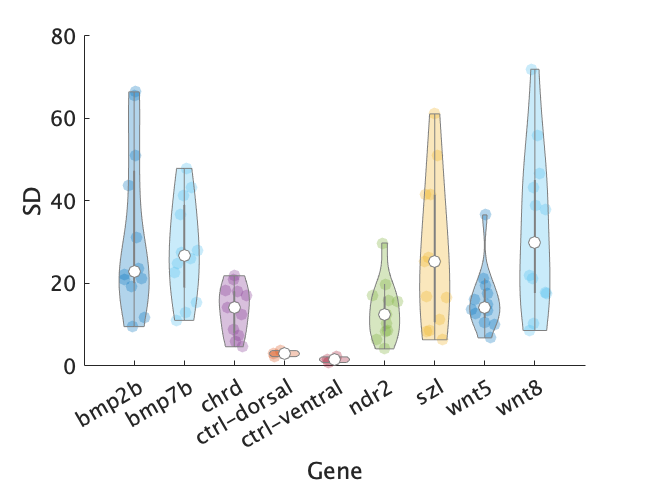

Ngene = size(datacell,2);
plotval = [];
plotidx = [];
for i = 1:Ngene
    genelabel = string(datacell{i}.genename);
    Ndata = size(datacell{i}.data,2);
    for j = 1:Ndata
        if ~isstruct(datacell{i}.data{j})
            continue
        end
        plotval = [plotval, datacell{i}.data{j}.stdres];
        plotidx = [plotidx, genelabel];
    end
end
close all
violinplot(plotval, plotidx);
xlabel("Gene")
ylabel("SD")
saveas(gcf, "SDvsGene_ver6.png")

save("SDvsGene_ver6.mat")

% 輝度分布 各データの真ん中のスライスでの画面全体での分布を全データで出してみて内田さんにみてもらう
% バックグラウンドの比較 データとバックグラウンドで同じ処理をして、いくつ検出されたかを/スライスで出す
% excelに検出個数とスライス枚数も記載する欄を作る

## ndr2

%{
range = 1:8;
tif_filename_list = exceldata{range,2};
data = exceldata{range,4:10};
ndr2_cell = {};
for sampleIndex = 1:size(range,2)
    sampleData = data(sampleIndex,:);
    figFilename = tif_filename_list{sampleIndex};
    ROIFilename = append(figFilename(1:end-4), ".zip");
    tifData = readTifSeq(append("RawData/", figFilename));
    tmrData = tifData(1:2:end,:,:);
    figSize = size(tifData, 3);
    ROIs = readROIs(append("RawData/", ROIFilename), figSize);
    Npages = size(tifData, 1)/2;
    param = sampleData([1,4,2,5,3,6,7]);

    NsignalInROI_list = zeros(1,size(ROIs, 1), "uint16");
    ROIBoundaries = zeros(figSize, "logical");
    for i = 1:size(ROIs, 1)
        ROIBoundariesIndex = bwboundaries(squeeze(ROIs(i,:,:)));
        ROIBoundaries(sub2ind([figSize, figSize], ROIBoundariesIndex{1}(:,1), ROIBoundariesIndex{1}(:,2))) = true;
    end
    for page = 1:Npages
        FP = highlightFP(squeeze(tmrData(page,:,:)), param);
        NsignalInROI = zeros(1,size(ROIs, 1), "uint16");
        for i = 1:size(ROIs, 1)
            CC = bwconncomp(squeeze(ROIs(i,:,:)) & FP);
            NsignalInROI(i) = CC.NumObjects;
        end
        NsignalInROI_list = NsignalInROI_list+NsignalInROI;
    end
    ndr2_cell{sampleIndex} = NsignalInROI_list;
end
%}

## bmp2b

%{
range = 10:17;
tif_filename_list = exceldata{range,2};
data = exceldata{range,4:10};
bmp2b_cell = {};
for sampleIndex = 1:size(range,2)
    sampleData = data(sampleIndex,:);
    figFilename = tif_filename_list{sampleIndex};
    ROIFilename = append(figFilename(1:end-4), ".zip");
    tifData = readTifSeq(append("RawData/", figFilename));
    tmrData = tifData(1:2:end,:,:);
    figSize = size(tifData, 3);
    ROIs = readROIs(append("RawData/", ROIFilename), figSize);
    Npages = size(tifData, 1)/2;
    param = sampleData([1,4,2,5,3,6,7]);

    NsignalInROI_list = zeros(1,size(ROIs, 1), "uint16");
    ROIBoundaries = zeros(figSize, "logical");
    for i = 1:size(ROIs, 1)
        ROIBoundariesIndex = bwboundaries(squeeze(ROIs(i,:,:)));
        ROIBoundaries(sub2ind([figSize, figSize], ROIBoundariesIndex{1}(:,1), ROIBoundariesIndex{1}(:,2))) = true;
    end
    for page = 1:Npages
        FP = highlightFP(squeeze(tmrData(page,:,:)), param);
        NsignalInROI = zeros(1,size(ROIs, 1), "uint16");
        for i = 1:size(ROIs, 1)
            CC = bwconncomp(squeeze(ROIs(i,:,:)) & FP);
            NsignalInROI(i) = CC.NumObjects;
        end
        NsignalInROI_list = NsignalInROI_list+NsignalInROI;
    end
    bmp2b_cell{sampleIndex} = NsignalInROI_list;
end
%}

## chrd

%{
range = 19:30;
tif_filename_list = exceldata{range,2};
data = exceldata{range,4:10};
chrd_cell = {};
for sampleIndex = 1:size(range,2)
    sampleData = data(sampleIndex,:);
    figFilename = tif_filename_list{sampleIndex};
    ROIFilename = append(figFilename(1:end-4), ".zip");
    tifData = readTifSeq(append("RawData/", figFilename));
    tmrData = tifData(1:2:end,:,:);
    figSize = size(tifData, 3);
    ROIs = readROIs(append("RawData/", ROIFilename), figSize);
    Npages = size(tifData, 1)/2;
    param = sampleData([1,4,2,5,3,6,7]);

    NsignalInROI_list = zeros(1,size(ROIs, 1), "uint16");
    ROIBoundaries = zeros(figSize, "logical");
    for i = 1:size(ROIs, 1)
        ROIBoundariesIndex = bwboundaries(squeeze(ROIs(i,:,:)));
        ROIBoundaries(sub2ind([figSize, figSize], ROIBoundariesIndex{1}(:,1), ROIBoundariesIndex{1}(:,2))) = true;
    end
    for page = 1:Npages
        FP = highlightFP(squeeze(tmrData(page,:,:)), param);
        NsignalInROI = zeros(1,size(ROIs, 1), "uint16");
        for i = 1:size(ROIs, 1)
            CC = bwconncomp(squeeze(ROIs(i,:,:)) & FP);
            NsignalInROI(i) = CC.NumObjects;
        end
        NsignalInROI_list = NsignalInROI_list+NsignalInROI;
    end
    chrd_cell{sampleIndex} = NsignalInROI_list;
end
%}

## szl

%{
range = 32:37;
tif_filename_list = exceldata{range,2};
data = exceldata{range,4:10};
szl_cell = {};
for sampleIndex = 1:size(range,2)
    sampleData = data(sampleIndex,:);
    figFilename = tif_filename_list{sampleIndex};
    ROIFilename = append(figFilename(1:end-4), ".zip");
    tifData = readTifSeq(append("RawData/", figFilename));
    tmrData = tifData(1:2:end,:,:);
    figSize = size(tifData, 3);
    ROIs = readROIs(append("RawData/", ROIFilename), figSize);
    Npages = size(tifData, 1)/2;
    param = sampleData([1,4,2,5,3,6,7]);

    NsignalInROI_list = zeros(1,size(ROIs, 1), "uint16");
    ROIBoundaries = zeros(figSize, "logical");
    for i = 1:size(ROIs, 1)
        ROIBoundariesIndex = bwboundaries(squeeze(ROIs(i,:,:)));
        ROIBoundaries(sub2ind([figSize, figSize], ROIBoundariesIndex{1}(:,1), ROIBoundariesIndex{1}(:,2))) = true;
    end
    for page = 1:Npages
        FP = highlightFP(squeeze(tmrData(page,:,:)), param);
        NsignalInROI = zeros(1,size(ROIs, 1), "uint16");
        for i = 1:size(ROIs, 1)
            CC = bwconncomp(squeeze(ROIs(i,:,:)) & FP);
            NsignalInROI(i) = CC.NumObjects;
        end
        NsignalInROI_list = NsignalInROI_list+NsignalInROI;
    end
    szl_cell{sampleIndex} = NsignalInROI_list;
end
%}

## SDを計算

%{
ndr2_cell
sd_ndr2 = zeros(size(ndr2_cell));
for i = 1:size(ndr2_cell,2)
    sd_ndr2(i) = std(double(ndr2_cell{i}));
end
bmp2b_cell;
sd_bmp2b = zeros(size(bmp2b_cell));
for i = 1:size(bmp2b_cell,2)
    sd_bmp2b(i) = std(double(bmp2b_cell{i}));
end
chrd_cell;
sd_chrd = zeros(size(chrd_cell));
for i = 1:size(chrd_cell,2)
    sd_chrd(i) = std(double(chrd_cell{i}));
end
szl_cell;
sd_szl = zeros(size(szl_cell));
for i = 1:size(szl_cell,2)
    sd_szl(i) = std(double(szl_cell{i}));
end
%}

%{
plotval = zeros(1,size(sd_ndr2,2)+size(sd_bmp2b,2)+size(sd_chrd,2)+size(sd_szl,2));
plotidx = strings(1,size(sd_ndr2,2)+size(sd_bmp2b,2)+size(sd_chrd,2)+size(sd_szl,2));
plotval(1:size(sd_ndr2,2)) = sd_ndr2;
plotidx(1:size(sd_ndr2,2)) = "ndr2";
plotval(size(sd_ndr2,2)+1:size(sd_ndr2,2)+size(sd_bmp2b,2)) = sd_bmp2b;
plotidx(size(sd_ndr2,2)+1:size(sd_ndr2,2)+size(sd_bmp2b,2)) = "bmp2b";
plotval(size(sd_ndr2,2)+size(sd_bmp2b,2)+1:size(sd_ndr2,2)+size(sd_bmp2b,2)+size(sd_chrd,2)) = sd_chrd;
plotidx(size(sd_ndr2,2)+size(sd_bmp2b,2)+1:size(sd_ndr2,2)+size(sd_bmp2b,2)+size(sd_chrd,2)) = "chrd";
plotval(size(sd_ndr2,2)+size(sd_bmp2b,2)+size(sd_chrd,2)+1:size(sd_ndr2,2)+size(sd_bmp2b,2)+size(sd_chrd,2)+size(sd_szl,2)) = sd_szl;
plotidx(size(sd_ndr2,2)+size(sd_bmp2b,2)+size(sd_chrd,2)+1:size(sd_ndr2,2)+size(sd_bmp2b,2)+size(sd_chrd,2)+size(sd_szl,2)) = "szl";
close
violinplot(plotval, plotidx);
xlabel("Gene")
ylabel("SD")
saveas(gcf, "SDvsGene.png")
close
%}

%{
range = 1:8;
writematrix(round(sd_ndr2,1).',"smFISH_parametas.xlsx","range",append("L",num2str(range(1)+1),":L",num2str(range(end)+1)));

range = 10:17;
writematrix(round(sd_bmp2b,1).',"smFISH_parametas.xlsx","range",append("L",num2str(range(1)+1),":L",num2str(range(end)+1)));

range = 19:30;
writematrix(round(sd_chrd,1).',"smFISH_parametas.xlsx","range",append("L",num2str(range(1)+1),":L",num2str(range(end)+1)));

range = 32:37;
writematrix(round(sd_szl,1).',"smFISH_parametas.xlsx","range",append("L",num2str(range(1)+1),":L",num2str(range(end)+1)));
%}